# Case Study for CCWI2016

Below, we provide a template solution on how to design an Arsenite contamination simulator based on EPANET and EPANET-MSX using the EPANET-MATLAB Toolkit. More about example: 

[https://zenodo.org/record/831493#.XvnadWgzaUl](https://zenodo.org/record/831493#.XvnadWgzaUl) 

[https://github.com/KIOS-Research/CCWI2016](https://github.com/KIOS-Research/CCWI2016)

## Clear - Start Toolkit

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


## Load EPANET Network and MSX

G = epanet('BWSN_Network_1.inp'); % Load EPANET Input file

EPANET version {20303} loaded (EMT version {v2.3.03 - Last Update: 02/01/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "BWSN_Network_1.inp"...
Input File "BWSN_Network_1.inp" loaded successfully.


G.loadMSXFile('Arsenite.msx'); % Load MSX file

% Sensor locations
sensor_id = {'JUNCTION-17', 'JUNCTION-83', 'JUNCTION-122', 'JUNCTION-31', 'JUNCTION-45'};
sensor_index = G.getNodeIndex(sensor_id);

## Simulation Setup

t_d = 5; % days
G.setTimeSimulationDuration(t_d*24*60*60); % Set simulation duration of 5 days

## Get Network data

demand_pattern = G.getPattern;
roughness_coeff = G.getLinkRoughnessCoeff;
node_id = G.getNodeNameID;

G.setMSXTimeStep(3600)

## Scenarios

Ns = 100; % Number of scenarios to simulate
u_p = 0.20; % pattern uncertainty
u_r = 0.20; % roughness coefficient uncertainty
max_inj_conc = 2.0;
inj_start_time = 2*48; % after day 2 (Dt = 30min)
inj_duration = 24; % maximum duration of 12 hours
inj_sc=[randi(G.NodeCount,Ns,1), max_inj_conc*rand(Ns,1), randi(48,Ns,1)+inj_start_time, randi(inj_duration,Ns,1)]; % Injection location, magnitude, start time, duration

## Run epochs

tic
for i = 1:Ns
    disp(['Iteration ', int2str(i)])
    % Randomize hydraulics
    r_p = -u_p + 2*u_p.*rand(size(demand_pattern,1),size(demand_pattern,2));
    new_demand_pattern = demand_pattern + demand_pattern.*r_p;
    G.setPatternMatrix(new_demand_pattern); % Set new patterns
    r_r = -u_r + 2*u_r.*rand(size(roughness_coeff,1),size(roughness_coeff,2));
    new_roughness_coeff = roughness_coeff + roughness_coeff.*r_r;
    G.setLinkRoughnessCoeff(new_roughness_coeff); % Set new roughness coefficients
    % Randomize injection
    G.setMSXSources(node_id(inj_sc(i,1)), 'AsIII', 'Setpoint', inj_sc(i,2), 'AS3PAT'); % Specify Arsenite injection source
    as3_pat = zeros(1, t_d*48);
    as3_pat(inj_sc(i,3):(inj_sc(i,3)+inj_sc(i,4))) = 1; % 
    G.setMSXPattern('AS3PAT',as3_pat); % Set pattern for injection
    Q{i} = G.getMSXComputedQualityNode(sensor_index); % Solve hydraulics and MSX quality dynamics
    G.setMSXSources(node_id(inj_sc(i,1)), 'AsIII', 'Setpoint', 0, 'AS3PAT'); % Reset injection source
end

Iteration 1
Iteration 2
Iteration 3
Iteration 4
Iteration 5
Iteration 6
Iteration 7
Iteration 8
Iteration 9
Iteration 10
Iteration 11
Iteration 12
Iteration 13
Iteration 14
Iteration 15
Iteration 16
Iteration 17
Iteration 18
Iteration 19
Iteration 20
Iteration 21
Iteration 22
Iteration 23
Iteration 24
Iteration 25
Iteration 26
Iteration 27
Iteration 28
Iteration 29
Iteration 30
Iteration 31
Iteration 32
Iteration 33
Iteration 34
Iteration 35
Iteration 36
Iteration 37
Iteration 38
Iteration 39
Iteration 40
Iteration 41
Iteration 42
Iteration 43
Iteration 44
Iteration 45
Iteration 46
Iteration 47
Iteration 48
Iteration 49
Iteration 50
Iteration 51
Iteration 52
Iteration 53
Iteration 54
Iteration 55
Iteration 56
Iteration 57
Iteration 58
Iteration 59
Iteration 60
Iteration 61
Iteration 62
Iteration 63
Iteration 64
Iteration 65
Iteration 66
Iteration 67
Iteration 68
Iteration 69
Iteration 70
Iteration 71
Iteration 72
Iteration 73
Iteration 74
Iteration 75
Iteration 76
Iteration 77
Iteratio

toc

Elapsed time is 332.116089 seconds.


G.unloadMSX;

## Plot results

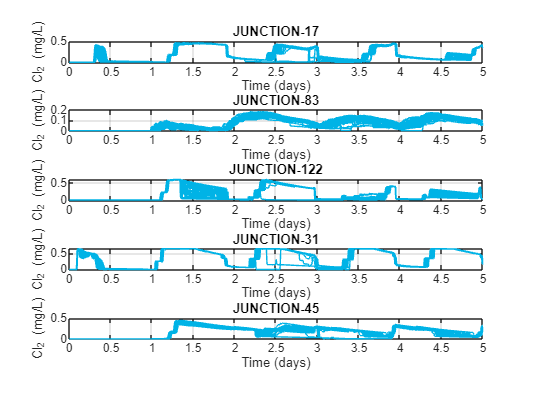

for i = 1:Ns
    for j = 1:length(sensor_index)
       subplot(5,1,j)
       plot(Q{i}.Time/24/60/60, Q{i}.Quality{j}(:,1),'-','Color',[0,0.7,0.9]); hold on; grid on
    end
end
for i = 1:length(sensor_index)
   subplot(5,1,i)
   title(sensor_id{i})
   ylabel('Cl_2 (mg/L)')
   xlabel('Time (days)')
end